modelName = 'tiny-complex-yolov4-pandaset';
mdl = downloadPretrainedComplexYOLOv4(modelName);
net = mdl.net; 

outputFolder = 'test2_pcd/';
path = 'test2_pcd/';
lidarData = fileDatastore(path,'ReadFcn',@(x) pcread(x));

Labels = timetable2table(gTruth.LabelData);
boxLabels = Labels(:,"boat");

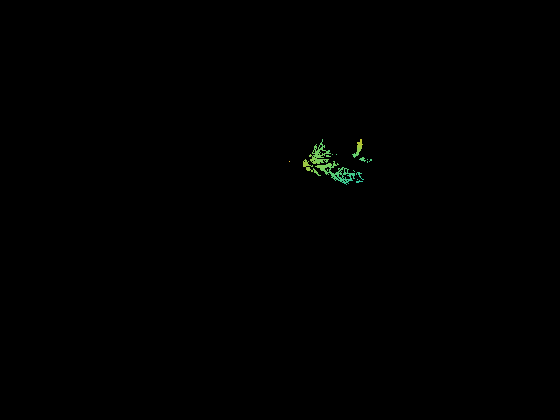

figure
ptCld = read(lidarData);
ax = pcshow(ptCld.Location);
set(ax,'XLim',[-50 50],'YLim',[-40 40]);
zoom(ax,2.5);
axis off;

xMin = -0.0;     % Minimum value along X-axis.
yMin = 0.0;  % Minimum value along Y-axis.
zMin = -100.0;    % Minimum value along Z-axis.
xMax = 200.3;   % Maximum value along X-axis.
yMax = 200.3;   % Maximum value along Y-axis.
zMax = 200.0;     % Maximum value along Z-axis.

bevHeight = 608;
bevWidth = 608;

gridW = (yMax - yMin)/bevWidth;
gridH = (xMax - xMin)/bevHeight;
gridW

gridW = 0.3294

gridH

gridH = 0.3294

gridParams = {{xMin,xMax,yMin,yMax,zMin,zMax},{bevWidth,bevHeight},{gridW,gridH}};

writeFiles = true;
if writeFiles
    transformPCtoBEV(lidarData,boxLabels,gridParams,outputFolder);
end

dataPath = fullfile(outputFolder,'BEVImages');
imds = imageDatastore(dataPath);

labelPath = fullfile(outputFolder,'Cuboids','BEVGroundTruthLabels.mat');
load(labelPath,'processedLabels');
blds = boxLabelDatastore(processedLabels);

[imds,blds] = removeEmptyData(imds,blds);

rng(0);
shuffledIndices = randperm(size(imds.Files,1));
idx = floor(0.6 * length(shuffledIndices));


imdsTrain = subset(imds,shuffledIndices(1:idx));
imdsTest = subset(imds,shuffledIndices(idx+1:end));

bldsTrain = subset(blds,shuffledIndices(1:idx));
bldsTest = subset(blds,shuffledIndices(idx+1:end));

trainData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

%validateInputDataComplexYOLOv4(trainData);
% validateInputDataComplexYOLOv4(testData);

networkInputSize = [608 608 3];
isRotRect = true;
preprocessedTrainingData = transform(trainData,@(data)preprocessData(data,networkInputSize,isRotRect));

data = read(preprocessedTrainingData);

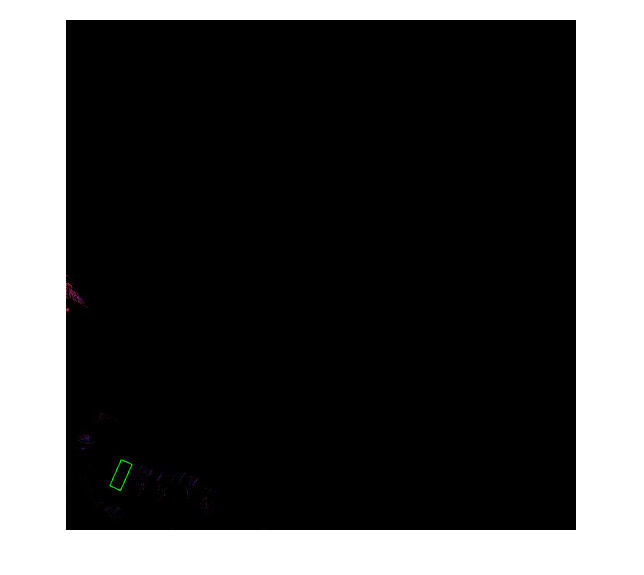

I = data{1,1};
bbox = data{1,2};
labels = data{1,3};
helperDisplayBoxes(I,bbox,labels);

reset(preprocessedTrainingData);

rng(0)
isRotRect = false;
trainingDataForEstimation = transform(trainData,@(data)preprocessData(data,networkInputSize,isRotRect));
numAnchors = 9;
[anchorBoxes,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors)

anchorBoxes =     14    34
    15    40
    15    35
    14    37
    17    33
    19    39
    18    44
    14    35
    16    35


meanIoU = 0.9927

% Specify the class names to use for training.
classNames = {'boat'};
[net,networkOutputs,anchorBoxes] = configureComplexYOLOv4(net,classNames,anchorBoxes,modelName);

maxEpochs = 90;
miniBatchSize = 2;
learningRate = 0.001;
warmupPeriod = 1000;
l2Regularization = 0.001;
penaltyThreshold = 0.5;
velocity = [];

if canUseParallelPool
   dispatchInBackground = true;
else
   dispatchInBackground = false;
end

mbqTrain = minibatchqueue(preprocessedTrainingData,2, ...
        "MiniBatchSize",miniBatchSize,...
        "MiniBatchFcn",@(images,boxes,labels) createBatchData(images,boxes,labels,classNames), ...
        "MiniBatchFormat",["SSCB",""],...
        "DispatchInBackground",dispatchInBackground,...
        "OutputCast",["","double"]);

Epoch : 1 | Iteration : 1 | Learning Rate : 1e-15 | Total Loss : 5278.5879 | Box Loss : 26.997 | Object Loss : 5250.3418 | Class Loss : 1.2489
Epoch : 1 | Iteration : 11 | Learning Rate : 1.4641e-11 | Total Loss : 5262.7783 | Box Loss : 13.2459 | Object Loss : 5248.8916 | Class Loss : 0.64073
Epoch : 1 | Iteration : 21 | Learning Rate : 1.9448e-10 | Total Loss : 5268.2471 | Box Loss : 18.8252 | Object Loss : 5247.978 | Class Loss : 1.4439
Epoch : 1 | Iteration : 31 | Learning Rate : 9.2352e-10 | Total Loss : 5292.313 | Box Loss : 16.6348 | Object Loss : 5274.6533 | Class Loss : 1.0247
Epoch : 1 | Iteration : 41 | Learning Rate : 2.8258e-09 | Total Loss : 5267.2314 | Box Loss : 10.8323 | Object Loss : 5255.8945 | Class Loss : 0.50432
Epoch : 1 | Iteration : 51 | Learning Rate : 6.7652e-09 | Total Loss : 5223.2246 | Box Loss : 30.6624 | Object Loss : 5191.3677 | Class Loss : 1.1945
Epoch : 1 | Iteration : 61 | Learning Rate : 1.3846e-08 | Total Loss : 5143.8716 | Box Loss : 19.9738 | Obj

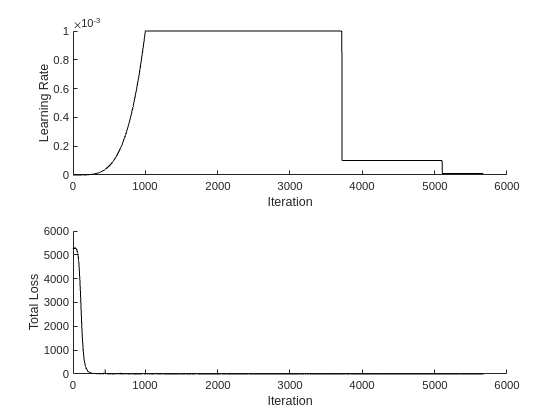

doTraining = true;

if doTraining
    iteration = 0;
   
    % Create subplots for the learning rate and mini-batch loss.
    fig = figure;
    [lossPlotter, learningRatePlotter] = configureTrainingProgressPlotter(fig);

    % Custom training loop.
    for epoch = 1:maxEpochs
          
        reset(mbqTrain);
        shuffle(mbqTrain);
        
        while(hasdata(mbqTrain))
            iteration = iteration + 1;
           
            [XTrain,YTrain] = next(mbqTrain);
            
            % Evaluate the model gradients and loss using dlfeval and the
            % modelGradients function.
            [gradients,state,lossInfo] = dlfeval(@modelGradients,net,XTrain,YTrain,anchorBoxes,penaltyThreshold,networkOutputs);
    
            % Apply L2 regularization.
            gradients = dlupdate(@(g,w) g + l2Regularization*w, gradients, net.Learnables);
    
            % Determine the current learning rate value.
            currentLR = piecewiseLearningRateWithWarmup(iteration,epoch,learningRate,warmupPeriod,maxEpochs);
            
            % Update the network learnable parameters using the SGDM optimizer.
            [net,velocity] = sgdmupdate(net,gradients,velocity,currentLR);
    
            % Update the state parameters of dlnetwork.
            net.State = state;
            
            % Display progress.
            if mod(iteration,10)==1
                displayLossInfo(epoch,iteration,currentLR,lossInfo);
            end
                
            % Update training plot with new points.
            updatePlots(lossPlotter,learningRatePlotter,iteration,currentLR,lossInfo.totalLoss);
        end
    end
else
    net = mdl.net;
    anchorBoxes = mdl.anchorBoxes;
end

% Create a table to hold the bounding boxes, scores, and labels returned by
% the detector. 
results = table('Size',[0 3], ...
    'VariableTypes',{'cell','cell','cell'}, ...
    'VariableNames',{'Boxes','Scores','Labels'});

% Run the detector on images in the test set and collect the results.
reset(testData)
while hasdata(testData)
    % Read the datastore and get the image.
    data = read(testData);
    image = data{1,1};
    
    % Run the detector.
    executionEnvironment = 'auto';
    [bboxes,scores,labels] = detectComplexYOLOv4(net,image,anchorBoxes,classNames,executionEnvironment);
    
    % Collect the results.
    tbl = table({bboxes},{scores},{labels},'VariableNames',{'Boxes','Scores','Labels'});
    results = [results; tbl];
end

% Evaluate the object detector using the average precision metric.
metrics = evaluateDetectionAOS(results, testData)

metrics = 1×5 table
              AOS        AP       OrientationSimilarity      Precision         Recall    
            _______    _______    _____________________    _____________    _____________

    boat    0.90067    0.90361        {84×1 double}        {84×1 double}    {84×1 double}


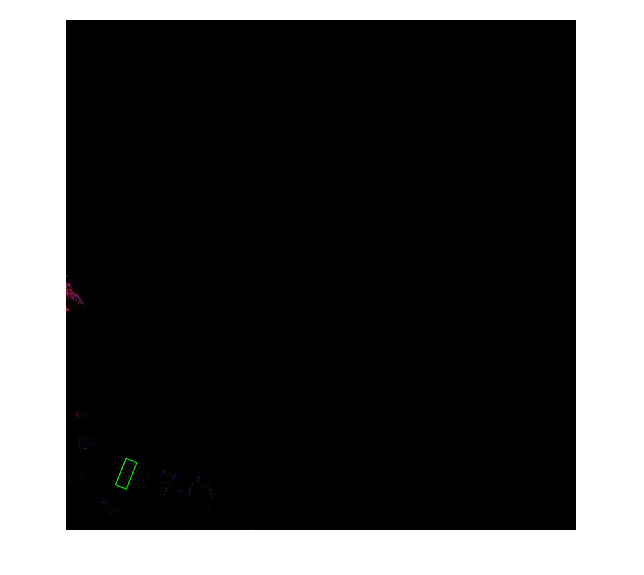

% Read the datastore.
reset(testData)
data = read(testData);

% Get the image.
I = data{1,1};

% Run the detector.
executionEnvironment = 'auto';
[bboxes,scores,labels] = detectComplexYOLOv4(net,I,anchorBoxes,classNames,executionEnvironment);

% Display the output.
figure
helperDisplayBoxes(I,bboxes,labels);

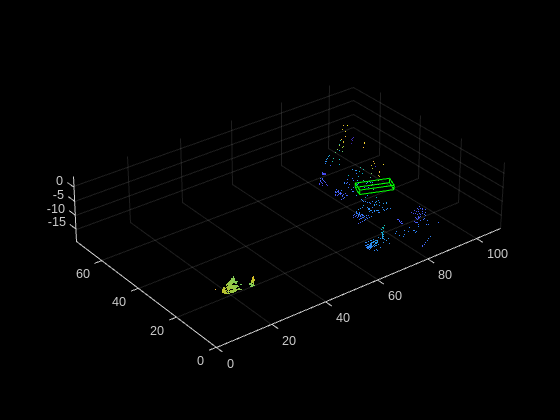

lidarTestData = subset(lidarData,shuffledIndices(idx+1:end));
ptCld = read(lidarTestData);
[ptCldOut,bboxCuboid] = transferbboxToPointCloud(bboxes,gridParams,ptCld);
helperDisplayBoxes(ptCldOut,bboxCuboid,labels);

function data = preprocessData(data,targetSize,isRotRect)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.
for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    % Convert an input image with a single channel to three channels.
    if numel(imgSize) < 3 
        I = repmat(I,1,1,3);
    end
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);

    if ~isRotRect
        bboxes = bboxes(:,1:4);
    end
    
    data(ii, 1:2) = {I,bboxes};
end
end
function helperDisplayBoxes(obj,bboxes,labels)
% Display the boxes over the image and point cloud.
    figure
    if ~isa(obj,'pointCloud')
        imshow(obj)
        shape = 'rectangle';
    else
        pcshow(obj.Location);
        shape = 'cuboid';
    end
    showShape(shape,bboxes(labels=='boat',:),...
                  'Color','green','LineWidth',0.5);;
end
function [XTrain,YTrain] = createBatchData(data,groundTruthBoxes,groundTruthClasses,classNames)
% Return images combined along the batch dimension in XTrain and
% normalized bounding boxes concatenated with classIDs in YTrain.

    % Concatenate images along the batch dimension.
    XTrain = cat(4,data{:,1});
    
    % Get class IDs from the class names.
    classNames = repmat({categorical(classNames')},size(groundTruthClasses));
    [~,classIndices] = cellfun(@(a,b)ismember(a,b),groundTruthClasses,classNames,'UniformOutput',false);
    
    % Append the label indexes and training image size to scaled bounding boxes
    % and create a single cell array of responses.
    combinedResponses = cellfun(@(bbox,classid)[bbox,classid],groundTruthBoxes,classIndices,'UniformOutput',false);
    len = max(cellfun(@(x)size(x,1),combinedResponses));
    paddedBBoxes = cellfun(@(v) padarray(v,[len-size(v,1),0],0,'post'),combinedResponses,'UniformOutput',false);
    YTrain = cat(4,paddedBBoxes{:,1});
end
function [gradients,state,info] = modelGradients(net,XTrain,YTrain,anchors,penaltyThreshold,networkOutputs)

    inputImageSize = size(XTrain,1:2);
    
    % Gather the ground truths in the CPU for postprocessing.
    YTrain = gather(extractdata(YTrain));
    
    % Extract the predictions from the network.
    [YPredCell,state] = complexYOLOv4Forward(net,XTrain,networkOutputs,anchors);
    
    % Gather the activations in the CPU for postprocessing and extract dlarray data. 
    gatheredPredictions = cellfun(@ gather,YPredCell(:,1:8),'UniformOutput',false); 
    gatheredPredictions = cellfun(@ extractdata, gatheredPredictions,'UniformOutput', false);
    
    % Convert predictions from grid cell coordinates to box coordinates.
    tiledAnchors = generateTiledAnchorsComplexYolov4(gatheredPredictions(:,2:5),anchors);
    gatheredPredictions(:,2:5) = applyAnchorBoxOffsetsComplexYolov4(tiledAnchors,gatheredPredictions(:,2:5),inputImageSize);
    
    % Generate targets for predictions from the ground truth data.
    [boxTarget,objectnessTarget,classTarget,objectMaskTarget,boxErrorScale] = generateComplexYOLOv4Targets(gatheredPredictions,YTrain,inputImageSize,anchors,penaltyThreshold);
    
    % Compute the loss.
    boxLoss = bboxOffsetLoss(YPredCell(:,[2 3 9 10 6 7]),boxTarget,objectMaskTarget,boxErrorScale);
    objLoss = objectnessLoss(YPredCell(:,1),objectnessTarget,objectMaskTarget);
    clsLoss = classConfidenceLoss(YPredCell(:,8),classTarget,objectMaskTarget);
    totalLoss = boxLoss + objLoss + clsLoss;
    
    info.boxLoss = boxLoss;
    info.objLoss = objLoss;
    info.clsLoss = clsLoss;
    info.totalLoss = totalLoss;
    
    % Compute the gradients of learnables with regard to the loss.
    gradients = dlgradient(totalLoss,net.Learnables);
end
function [lossPlotter,learningRatePlotter] = configureTrainingProgressPlotter(f)
% Create the subplots to display the loss and learning rate.

    figure(f);
    clf
    subplot(2,1,1);
    ylabel('Learning Rate');
    xlabel('Iteration');
    learningRatePlotter = animatedline;
    subplot(2,1,2);
    ylabel('Total Loss');
    xlabel('Iteration');
    lossPlotter = animatedline;
end

function displayLossInfo(epoch,iteration,currentLR,lossInfo)
% Display loss information for each iteration.
    disp("Epoch : " + epoch + " | Iteration : " + iteration + " | Learning Rate : " + currentLR + ...
       " | Total Loss : " + double(gather(extractdata(lossInfo.totalLoss))) + ...
       " | Box Loss : " + double(gather(extractdata(lossInfo.boxLoss))) + ...
       " | Object Loss : " + double(gather(extractdata(lossInfo.objLoss))) + ...
       " | Class Loss : " + double(gather(extractdata(lossInfo.clsLoss))));
end

function updatePlots(lossPlotter,learningRatePlotter,iteration,currentLR,totalLoss)
% Update loss and learning rate plots.
    addpoints(lossPlotter,iteration,double(extractdata(gather(totalLoss))));
    addpoints(learningRatePlotter, iteration,currentLR);
    drawnow
end
function currentLR = piecewiseLearningRateWithWarmup(iteration,epoch,learningRate,warmupPeriod,numEpochs)
% The piecewiseLearningRateWithWarmup function computes the current
% learning rate based on the iteration number.
    persistent warmUpEpoch;
    
    if iteration <= warmupPeriod
        % Increase the learning rate for the number of iterations in the warmup period.
        currentLR = learningRate*((iteration/warmupPeriod)^4);
        warmUpEpoch = epoch;
    elseif iteration >= warmupPeriod && epoch < warmUpEpoch+floor(0.6*(numEpochs-warmUpEpoch))
        % After the warmup period, keep the learning rate constant if the remaining number of epochs is less than 60 percent. 
        currentLR = learningRate;
        
    elseif epoch >= warmUpEpoch + floor(0.6*(numEpochs-warmUpEpoch)) && epoch < warmUpEpoch+floor(0.9*(numEpochs-warmUpEpoch))
        % If the remaining number of epochs is more than 60 percent but less
        % than 90 percent, multiply the learning rate by 0.1.
        currentLR = learningRate*0.1;
        
    else
        % If more than 90 percent of the epochs remain, multiply the learning
        % rate by 0.01.
        currentLR = learningRate*0.01;
    end
end
function boxLoss = bboxOffsetLoss(boxPredCell,boxDeltaTarget,boxMaskTarget,boxErrorScaleTarget)
    lossX = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,1),boxDeltaTarget(:,1),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossY = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,2),boxDeltaTarget(:,2),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossW = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,3),boxDeltaTarget(:,3),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossH = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,4),boxDeltaTarget(:,4),boxMaskTarget(:,1),boxErrorScaleTarget));
    
    lossYaw1 = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,5),boxDeltaTarget(:,5),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossYaw2 = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,6),boxDeltaTarget(:,6),boxMaskTarget(:,1),boxErrorScaleTarget));
    
    boxLoss = lossX+lossY+lossW+lossH+lossYaw1+lossYaw2;
end
function clsLoss = classConfidenceLoss(classPredCell,classTarget,boxMaskTarget)
    clsLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),classPredCell,classTarget,boxMaskTarget(:,3)));
end
function objLoss = objectnessLoss(objectnessPredCell,objectnessDeltaTarget,boxMaskTarget)
    objLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),objectnessPredCell,objectnessDeltaTarget,boxMaskTarget(:,2)));
end